# Scene_Calibration

## Init

clc, clear

## params

bkg_path = "E:\project\CACTI\experiment\real_data\data\cap_20201201\black\zeros.tif"

bkg_path = "E:\project\CACTI\experiment\real_data\data\cap_20201201\black\zeros.tif"

bkg_nomask_path = "E:\project\CACTI\experiment\real_data\data\cap_20201201\black\black_no_mask.tif"

bkg_nomask_path = "E:\project\CACTI\experiment\real_data\data\cap_20201201\black\black_no_mask.tif"

white_nomask_path = "E:\project\CACTI\experiment\real_data\data\cap_20201201\white\white.tif"

white_nomask_path = "E:\project\CACTI\experiment\real_data\data\cap_20201201\white\white.tif"



% meas_path = 'E:\project\CACTI\experiment\real_data\data\scene\scene_dhc_static_20201116\'
meas_path = 'E:\project\CACTI\experiment\real_data\data\cap_20201201\cap_scene\dynamic_box3\'

meas_path = 'E:\project\CACTI\experiment\real_data\data\cap_20201201\cap_scene\dynamic_box3\'

meas_names  = ["dynamic_box3.tif"];

meas_path = char(meas_path);
save_path = meas_path;

% mask_size = [2500 2500]
mask_size = [1024,1024]

mask_size =         1024        1024


% mask_size = [256,256]
% mask_size = [1000,1000]

% roi_rect = [1200, 2150,mask_size-1]; % [xmin, ymin, width, height]
roi_rect = [1535, 2440,mask_size(2)-1, mask_size(1)-1]; % [xmin, ymin, width, height]

## find image


% background and  lumi
bkg = double(imread(bkg_path));
bkg_nomask = double(imread(bkg_nomask_path));
white_nomask = double(imread(white_nomask_path));

% mask
if exist('meas_names','var')
    file_num = numel(meas_names);
else
    files = dir([meas_path '*.tif']);
    file_names = {files.name};
    file_num = numel(file_names);
end
disp([num2str(file_num) ' files found'])

1 files found


## crop, de_background, de_illumination

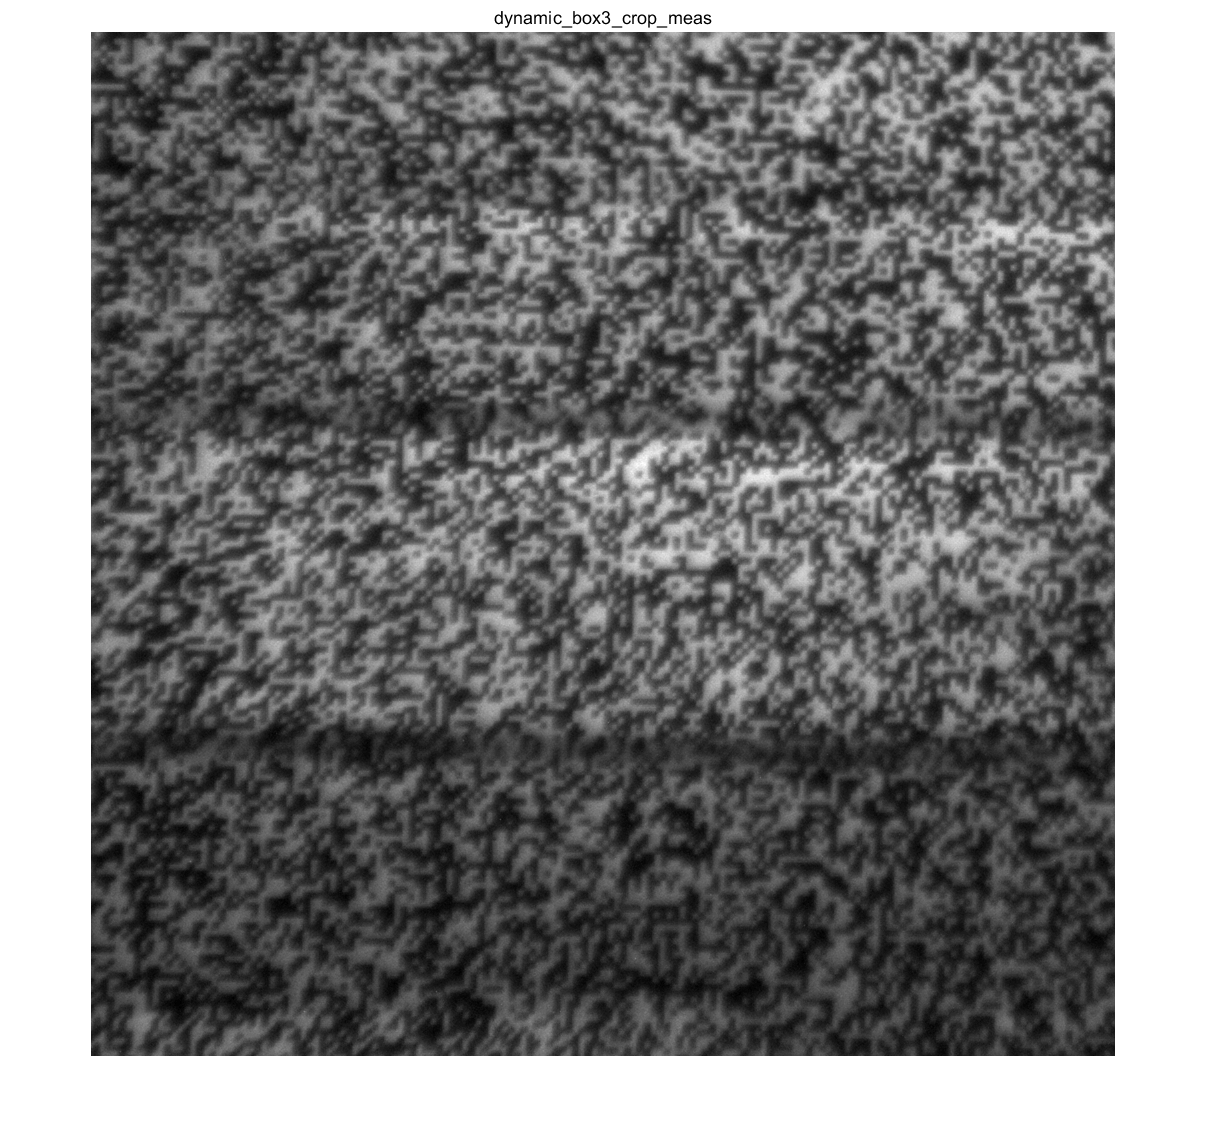

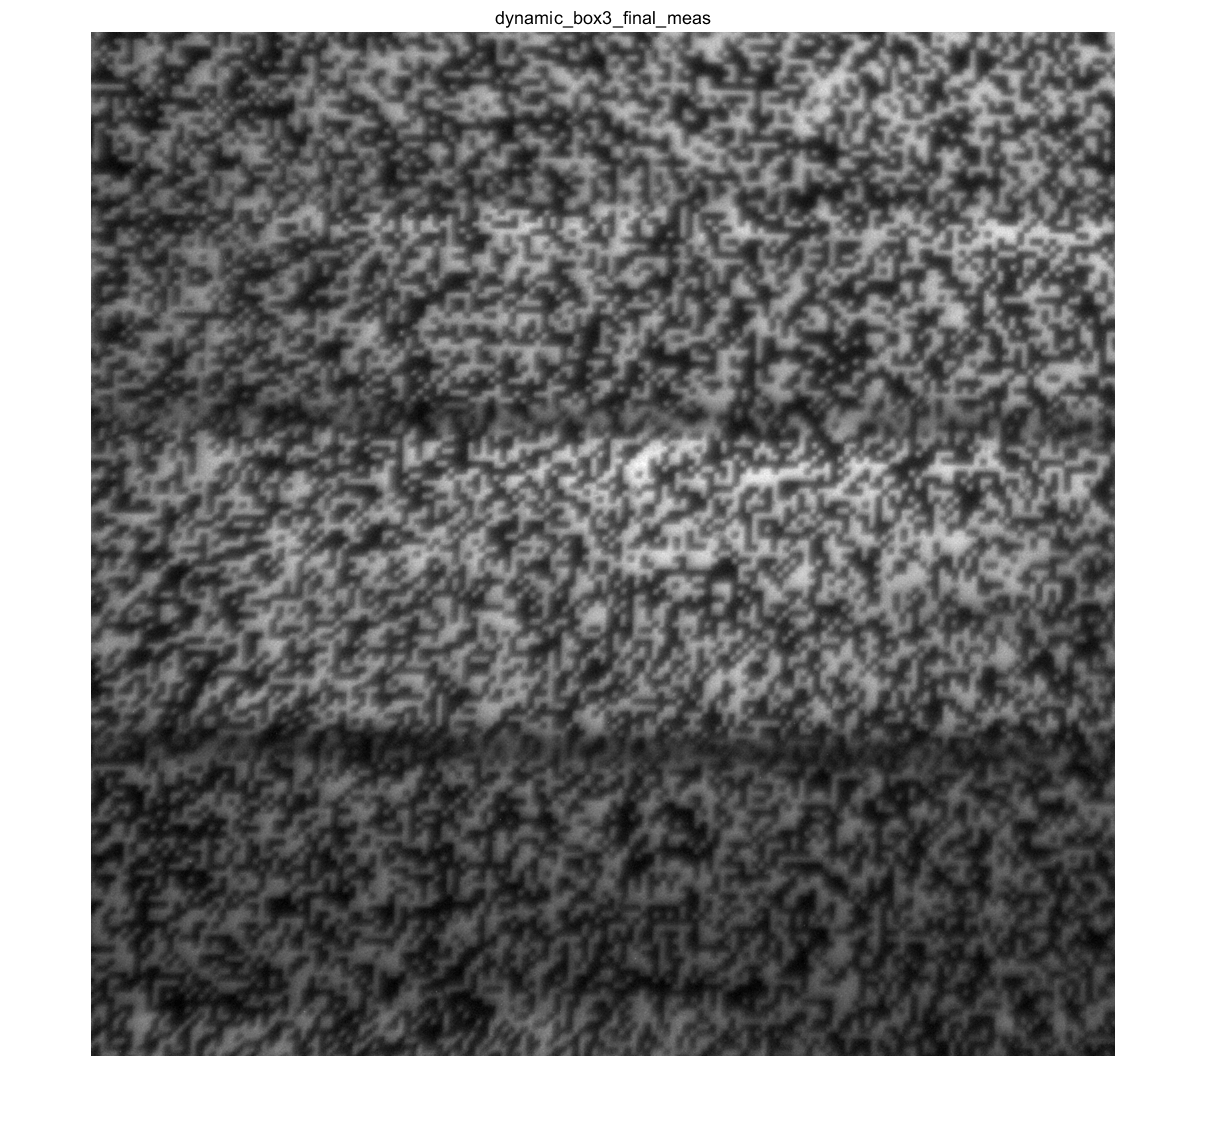

MEAS: max 89.00, mean 41.20, min 18.00

% bkg and white
crop_bkg = imcrop(bkg, roi_rect);
crop_bkg_nomask = imcrop(bkg_nomask, roi_rect);
crop_white = imcrop(white_nomask, roi_rect);
debkg_crop_white = crop_white - crop_bkg_nomask;

for k = 1:file_num
    % read
    if exist('meas_names','var')
        meas_name = meas_names{k};
    else
        meas_name = file_names{k};
    end

    src_meas = double(imread([char(meas_path) meas_name]));
    
    % crop
    crop_meas = imcrop(src_meas, roi_rect);
    % de_bkg
    debkg_crop_meas = crop_meas - crop_bkg;

    meas = debkg_crop_meas;
%     meas = crop_meas;
    
    
    % show
    figure
    imshow(crop_meas,[])
    title([meas_name(1:end-4) '_crop_meas'], 'Interpreter', 'none')
    figure
    imshow(meas,[])
    title([meas_name(1:end-4) '_final_meas'], 'Interpreter', 'none')

    % meas analysis
    mean_meas = mean(meas, 'all');
    max_meas = max(meas, [],'all');
    min_meas = min(meas, [],'all');
    hist_dt = meas;
    fprintf('MEAS: max %.2f, mean %.2f, min %.2f', max_meas, mean_meas, min_meas)
    
    % save
   save_name = [meas_name(1:end-4) '_roi' num2str(roi_rect(1)) '-' num2str(roi_rect(2)) '_sz' num2str(mask_size(2))] ;
   save([char(save_path),save_name,'.mat'], 'meas','debkg_crop_meas', 'crop_meas','src_meas','bkg');
end

## '